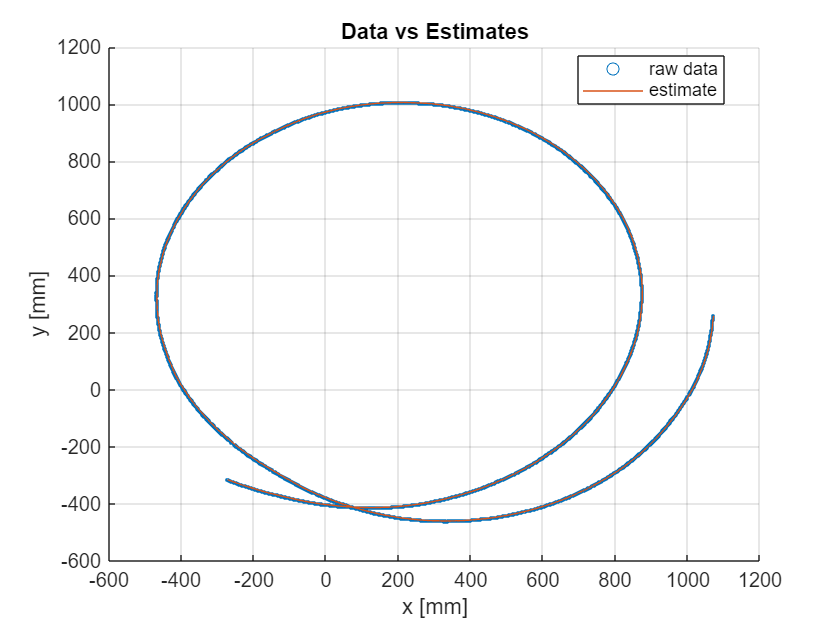

%#ok<*CLALL>

clear all;clc 


% Load data set data_20250902_1358_0.30L_0.15R
data = readtable('data_20250902_1358_0.30L_0.15R.csv', 'NumHeaderLines', 1);
data = table2array(data);


% Test run the extended Kalman Filter. 
u = [0.30; 0.15]; 
Q = [ ...
    0.0054 0.0000 0.0000; ...
    0.0000 0.0002 0.0000; ...
    0.0000 0.0000 0.0240]; 
R = [ ...
    0.0015^2 0; ...
    0        0.0015^2]; 
x_0 = [data(1, 2:3).'; 3*pi/2]; 
ekf = lab1EKF(x_0, Q, R); 
estimates = zeros(size(data, 1), 3);
P = zeros(size(data, 1), 3, 3);
for k = 1:size(data, 1)
    z = data(k, 2:3).'; 
    [estimates(k, :), P(k, :, :)] = ekf.update(u, z);
end

% Plot raw data. 
clf(); 
hold on;

scatter(data(:, 2), data(:, 3), 2);

% Plot estimates.  
plot(estimates(:, 1), estimates(:, 2));

xlabel('x [mm]');
ylabel('y [mm]');
title('Data vs Estimates');
legend('raw data', 'estimate', 'location', 'best')
grid on;
hold off; 

% error
detP = det(squeeze(P(end,:,:)))

detP = 1.3980e-13